# EAS 4610 Final Project - Solutions to Saint Venant's Equations to Study Floods in Rivers

## By: Ethan Losasso, Sara Delawalla, Abigail Russ

## Introduction

#### ***Main theme and importance:***

Since the time of ancient civilizations, hydrology has been used to understand the flow of water within river channels - a vital task for controlling water resources and mitigating potential damages caused by natural and unnatural flood events. Today's mathematical and technological knowledge allows us to model such flood events, using computing techniques and numerical schemes for solving partial differential equations to predict the behavior of a flood wave over time. 

#### ***What makes this project unique:***

Though this topic has been discussed in multiple papers, the parameters in each paper vary considerably. For our final project, we draw inspiration from two seperate papers. The general setup of the numerical methods, initial conditions, and boundary conditions are described by Sulistyono and Wiryanto (2017). The assumption of a rectangular channel and much of the background understanding of the equations and parameters are described by Changas and Souza (2005). We aim to test parameters from both papers in order to maintain an accurate representation of a river and a numerically stable solution. 

## Equations

#### ***Fundamental physical processes: ***

In this paper, the flood wave that will be modelled will act as a *dynamic wave, *meaning that it will be described as a shallow wave with one-dimensional flow that varies with time, hydrostatic pressure distribution (taking pressure out of the picture). This wave will initially enter the channel with a linear "triangular" influx, representing a flow field at the mouth of the river that linearly increases to some peak value at a specified time, and then linearly decreases back to the inital flow rate.

#### ***Relevant equations and derivations:***

This project will focus on Saint Venant's equations for dynamic waves as a basis to predict the flow field *Q(x,t)* and cross sectional area *A(x,t) *of a flood wave propagating through a river channel. The guiding partial differential equations for the dynamic wave take the form of an advection equation; specifically, we will use the flux form of the advection equation, as this still allows for mass conservation even when the horizontal velocity of fluid flow is varied over the cross sectional area. The general flux form of the advection equation as learned in class is $\frac{\partial J}{\partial t}+\frac{\partial }{\partial x}\left(\textrm{uJ}\right)=S\left(x,t\right)$, where u is fluid velocity and S(x,t) is the source of value J. In this equation, both fluid velocity and the value J vary with x. Keep this general equation in mind, as it will be used later to describe the behavior of the dynamic flood wave.

The two fundamental Saint-Venant equations for dynamic waves are the continuity equation and the momtentum equation. 

- 1) Continuity equation: $\frac{\textrm{𝜕𝐴}}{\textrm{𝜕𝑡}}+\frac{\textrm{𝜕𝑄}}{\partial x}=0$

- 2) Momentum equation: $\frac{\textrm{𝜕𝑄}}{\partial t}+\frac{\textrm{𝜕}}{\textrm{𝜕𝑥}}\left(\frac{{\textrm{𝑄}}^2 }{A}\right)+\textrm{𝑔𝐴}\left(\frac{\textrm{𝜕ℎ}}{\textrm{𝜕𝑥}}-\textrm{𝑆𝑜}\right)+\textrm{𝑔𝐴𝑆𝑓}=0$

The parameters in these equations are:

- Q = Discharge ($\frac{m^3 }{s}$)

- A = Cross sectional area ($m^2$)

- x = Distance down channel ($m$)

- t = Time ($s$)

- g = Gravitational acceleration ($\frac{m}{s^2 }$)

- S0 = Slope of the bottom of the channel ($\frac{m}{m}$)

- Sf = Friction slope / slope of the energy gradient

To calculate Sf, which is found in the final term of the dynamic wave momentum equation, the Manning formulation is used. This relates the flow field Q and cross sectional area A, as well as the roughness coeffictient (n) and the hyraulic radius (R):

- 3) Manning formulation (rearranged): $\textrm{Sf}=\frac{Q^2 n^2 }{A^2 R^{\frac{4}{3}} }$

The hydraulic radius, R, is calculated using the formula:

- 4) Hydraulic radius:$R=\frac{A}{P}=\frac{A}{\left(\frac{A}{B}*2\right)+B}$

Where P is the wetted perimeter, or the perimeter of the channel covered by water, and B is channel width. Both values are in meters..

Since the hydraulic radius varies as a function of the cross sectional area of the flood wave, this means *Sf* also varies as a function of cross sectional area. Through derivation, these four equations can be used to create a comprehensive equation for the discharge over space and time:

- 5) $\frac{\partial Q}{\partial t}+\alpha \left(\frac{\partial Q}{\partial x}\right)+\beta =0$

This equation closely resembles the original flux form of the advection equation mentioned earlier, with the beta term representing the sink of energy from friction. In this equation, the alpha and beta terms both change as a function of the parameters described previously:

- 6) $\alpha =2\frac{Q}{A}+\frac{\left(\frac{\textrm{gA}}{B}-\frac{Q^2 }{A^2 }\right)}{\left(\frac{Q}{A}\left(\frac{5}{3}-\frac{4}{3}\frac{R}{B}\right)\right)}$

- 7) $\beta =\textrm{gA}\left(\textrm{Sf}-\textrm{S0}\right)$

Prior to discretizing the equation and modelling the progression of the flow field, we must define initial and boundary conditions. The initial conditions for the Q and A parameters at time 0 are:

- 
$$Q\left(x,0\right)=Q_0$$


- 
$$A\left(x,0\right)=A_0$$


The upstream boundary conditions for Q are written as a series of conditional statements, defining a linear "triangular" influx that represents the flow field at the mouth of the river linearly increasing to a peak influx, $Q_p$, at a specified time, $t_p$, and then linearly decreases back to the inital flow rate,${\;Q}_0$, at a time, $t_b$. These statements are written as follows:

- 
$$Q\left(0,t\right)=Q_0 +\frac{\left(Q_p -Q_0 \right)}{t_p }t\;\textrm{for}\;0<t<t_p$$


- 
$$Q\left(0,t\right)=Q_p -\frac{\left(Q_p -Q_0 \right)}{t_b -t_p }\left(t-t_p \right)\;\textrm{for}\;t_p <t<t_b$$


- 
$$Q\left(0,t\right)=Q_0 \;\textrm{for}\;t>t_b$$


#### ***Assumptions:***

As mentioned before, this model assumes one-dimensional flow that varies with time and a hydrostatic pressure distribution (taking pressure out of the picture). It also assumes constant channel width (and a rectangular shape of the channel), constant roughness throughout the channel surface, and constant slope of the channel floor.

## Numerical Methods

#### ***Numerical methods used:***

To discretize the advection equation, one method we can use is a form of the upwind scheme described by Sulistyono and Wiryanto (2017). This paper follows a similar approach to modeling Saint Venant's equations for a dynamic wave as Changas and Souza (2005), yet uses an upwind forward Euler scheme to model the propgation of the flood wave. This method is an explicit finite difference method, where both time and space are discretized using the Forward Euler method:

- FE discretization (time): $\frac{\partial Q\left(x,t\right)}{\partial x}=\frac{Q_i^j -Q_{i-1}^j }{\Delta x}$

- FE discretization (space): $\frac{\partial Q\left(x,t\right)}{\partial x}=\frac{Q_i^{j+1} -Q_i^j }{\Delta t}$

Substituting these discretized steps into the discharge equation (equation 5), we can obtain a marching equation for Q, finding the values of Q at the next time step using information from the current and previous spatial steps at the current time step.

- Flow field marching equation: $Q_i^{j+1} =Q_i^j -\frac{\Delta t}{\Delta x}\left(\alpha_i^j \right)\left(Q_i^j -Q_{i-1}^j \right)+\beta_i^j \Delta t$

In this form, alpha and beta are also changing for each spatial step, and thus both need a marching equation as well. These are contained within the alpha and beta calculation functions towards the bottom of the document:

- Alpha marching equation:$\alpha_i^j =2\frac{Q_i^j }{A_i^j }+\frac{\left(\frac{gA_i^j }{B}-\frac{{Q_i^j }^2 }{{A_i^j }^2 }\right)}{\left(\frac{Q_i^j }{A_i^j }\left(\frac{5}{3}-\frac{4}{3}\frac{R_j^i }{B}\right)\right)}$

- Beta marching equation:$\beta =gA_i^j \left({\textrm{Sf}}_i^j -\textrm{S0}\right)$

We can then use the current cross-sectional area and the flow field at the next timestep and the current and previous spatial steps to compute the cross-sectional area at the next time step.

- Cross-sectional area marching equation: $A_i^{j+1} =A_i^j -\frac{\Delta t}{\Delta x}\left(Q_i^{j+1} -Q_{i-1}^{j+1} \right)$

To perform this quickly, we formulated a bidiagonal finite difference matrix for each time step. If the coefficient in front of the spatial derivative was constant, we could formulate this matrix once and use it for each time step. However, since the alpha coefficient also changes as a function of Q and A at each spatial step, the finite difference matrix must be created in a way that reflects this (in our code, it is created for each spatial step in the for loop that runs the model).

We chose this method mainly becuase it allows us to utilize known information from a previous spatial step and time step to predict the value at the next time step. This allows for a relatively simple, computationally inexpensive way to calculate the behavior of the flood wave at discrete points in the canal over discrete time intervals.

## Code for Methods and Results

*Setting parameters based on Sulistyono and Wiryanto (2017), with the alpha coefficient modified to fit a rectangular channel as described by Changas and Souza (2005):*

% Setting parameters (constants)
g = -9.81;   % gravitational constant (m/s^2)
B = 5;   % channel width (m)
n = 0.0138;   % roughness coefficient 
S0 = 0.0005;  % bed slope (m/m)
h0 = 2;   %channel depth (m)

% Setting initial conditions
Q0 = 3;   % steady state flow (m^3/s)
Qp = 12;   % max inflow (m^3/s)
A0 = B .* h0;   % steady state cross sectional area (m^2)

% Setting spatial parameters
dx = 100;  % spatial interval size (m)
xf = 1000;   % final x-value (m)
nx = xf ./ dx;   % number of space steps

% Setting temporal parameters
dt = 1;   % temporal interval size (s)
ti = 0;   % initial time (s)
tf = dt .* 100;   % final time (s)
nt = tf ./ dt;   % number of time steps

% Setting boundary condition peak influx time and base influx time
tp = nt ./ 4;   % peak wave flux timestep
tb = nt./ 2;   % base wave flux timestep

% Setting domain
xVec = 0:nx:xf;


*Running the model for set parameters (Attempt 1)*

[Q1, A1] = waveModel(Qp, Q0, A0, nx, nt, dx, dt, tp, tb, B, g, n, S0);

Plotting boundary condition progressions of Q as a function of time for attempt 1:

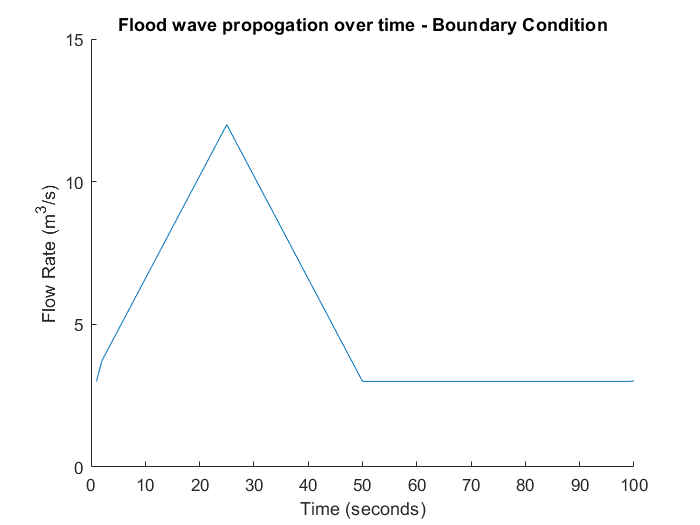

figure()
hold on
plot(1:100, Q1(1,1:end))
ylim([0,15])
xlim([0,100])
xlabel("Time (seconds)");
ylabel("Flow Rate (m^3/s)");
title("Flood wave propogation over time - Boundary Condition")
hold off

The boundary condition seems to have been correctly applied to the Q matrix, showing the change of flow rate into the channel mouth over time. The flood wave influx peaks at 25 second and returns to the base influx at 50 seconds. This looks similar to the inital plot found within the paper, with slightly different values for the peak influx time and boundary time. 

Plotting boundary condition progressions of Q and A as a function of time for all spatial steps for attempt 1:

figure()
hold on
for i = 1:nx
    plot(1:100, Q1(i,1:end))
end

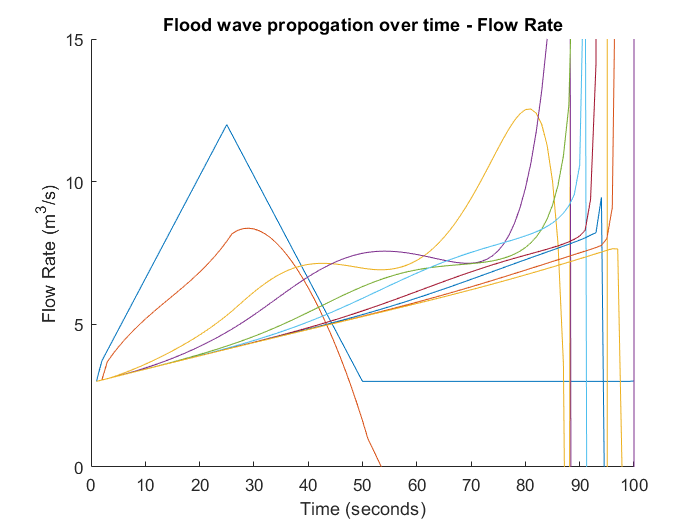

ylim([0,15])
xlim([0,100])
xlabel("Time (seconds)");
ylabel("Flow Rate (m^3/s)");
title("Flood wave propogation over time - Flow Rate")
hold off


figure()
hold on
for i = 1:nx
    plot(1:100, A1(i,1:end))
end

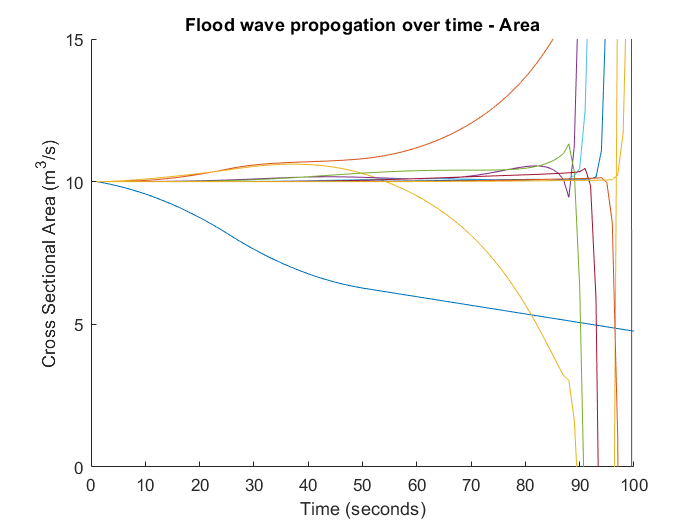

ylim([0,15])
xlim([0,100])
xlabel("Time (seconds)");
ylabel("Cross Sectional Area (m^3/s)");
title("Flood wave propogation over time - Area")
hold off

It is safe to say something is not working with the code for the propogation of the flood wave. There are a few places were issues may be arising. The alpha coefficient relies on both Q and A propogating correctly, and contributes to the solution significantly more than beta. The imaginary component to the solution, which is certainly incorrect, seems to propogate from the hydraulic radius term. 

Ideally, we would then use cross-sectional area and the constant width of the channel to calculate the change in wave depth in the channel over time, as *Changas and Souza (2005) *do. This is the advantage of using a rectangular channel.

*Function for full model to solve Q and A*

function [Q, A] = waveModel(Qp, Q0, A0, nx, nt, dx, dt, tp, tb, B, g, n, S0)  
    % Setting initial conditions and initializing Q(x,t) matrix and A(x,t) matrix
    Q = nan(nx, nt);
    Qinit = ones(nx, 1);
    Qinit = Q0 .* Qinit;
    Q(:, 1) = Qinit;
    
    A = nan(nx, nt);
    Ainit = ones(nx, 1);
    Ainit = A0 .* Ainit;
    A(:, 1) = Ainit;

    for j = 1 : nt - 1
        % Calculating the alpha and beta coefficients from previous time step
        [alphaVec] = alphaCalc(Q, A, j, nx, B, g);
        [betaVec] = betaCalc(Q, A, j, nx, B, g, n, S0);
        
        % Making FD matrix for flow field marching equation
        MQ = spdiags([(dt ./ dx) .* alphaVec, 1 - ((dt ./ dx) .* alphaVec)], -1:0, nx, nx);
        MQ(1,1) = 1;
        
        % Making FD matrix for cross-sectional area marching equation
        MA = spdiags([(dt./ dx) .* ones(nx,1), -(dt ./ dx) .* ones(nx,1)], -1:0, nx, nx);
        
        % Creating boundary condition vector for both sides of equation
        BC = BCFlow(j, tp, tb, Qp, Q0);
        
        % Running full model
        Q(1, j) = BC;
        Q(:, j + 1) = MQ * Q(:, j) + betaVec .* dt;
        A(:, j + 1) = A(:, j) + MA * Q(:, j + 1) ;
    end
end

#### ***Functions used within code:***

*Boundary condition function used in above model:*

function [BC] = BCFlow(t, tp, tb, Qp, Q0) 
    if t > 1 && t < tp
        BC = Q0 + (((Qp - Q0) ./ (tp)) .* t);
    elseif t == tp
        BC = Qp;
    elseif t > tp && t < tb
        BC = Qp - (((Qp - Q0) ./ (tb - tp)) .* (t - tp));
    else
        BC = Q0;
    end
end


*Function calculating the alpha coefficient at each time step:*

function [alphaVec] = alphaCalc(Q, A, j, nx, B, g)
    alphaVec = zeros(nx, 1);
    for i = 1 : nx
        R = A(i, j) ./ (((A(i, j) ./ B) .* 2) + B);      
        term1 = 2 .* (Q(i, j) ./ A(i, j));
        term2 = (g .* A(i, j)) ./ B;
        term3 = (Q(i, j) .^ 2) ./ (A(i, j) .^ 2);
        term4 = Q(i, j) ./ A(i, j);
        term5 = (5/3) - ((4/3) .* (R ./ B));
        alpha = term1 + ((term2 - term3) ./ (term4 .* term5));
        alphaVec(i) = alpha;
    end
end


*Function calculating the beta coefficient at each time step:*

function [betaVec] = betaCalc(Q, A, j, nx, B, g, n, S0)
    SfVec = ones(nx, 1);
    betaVec = ones(nx, 1);
    for i = 1 : nx
        R = (A(i, j)) ./ (((A(i, j) ./ B) .* 2) + B);
        Sf = ((Q(i, j) .^ 2) .* (n .^ 2)) ./ ((A(i, j) .^ 2) .* (R .^ (4/3)));
        SfVec(i) = Sf;
        beta = g .* A(i, j) .* (SfVec(i) - S0);
        betaVec(i) = beta;
    end
end


In conclusion, although the code does not work and produce results as intended, the logic behind the methods is clear. The general form is an advection equation, with the beta term acting as the sink. The alpha and beta coefficient represent the physical behavior and dependencies of the dynamic wave equation. Both the alpha and beta terms are dependent on both Q and A, as well as other physical parameters, such as the gravitational acceleration *g, *roughness coefficient *n, *etc. The dynamic wave is the most comprehensive wave equation to represent a flood wave, as it considers all terms of the momentum equation according to *Changas and Souza (2005), *so that would likely stay the same. Assuming the code worked properly, one interesting study would be to vary other terms over time, such as the slope of the river and the roughness coefficient. This could produce more realistic results. 

## References

Chagas, P., & Souza, R. (2005). Solution of Saint Venant's Equation to Study Flood in Rivers, through Numerical Methods. *Hydrology Days*. Retrieved from http://hydrologydays.colostate.edu/Papers_2005/Raimundo_paper_1.pdf. 

AIP Conference Proceedings 1867, 020020 (2017); https://doi.org/10.1063/1.4994423